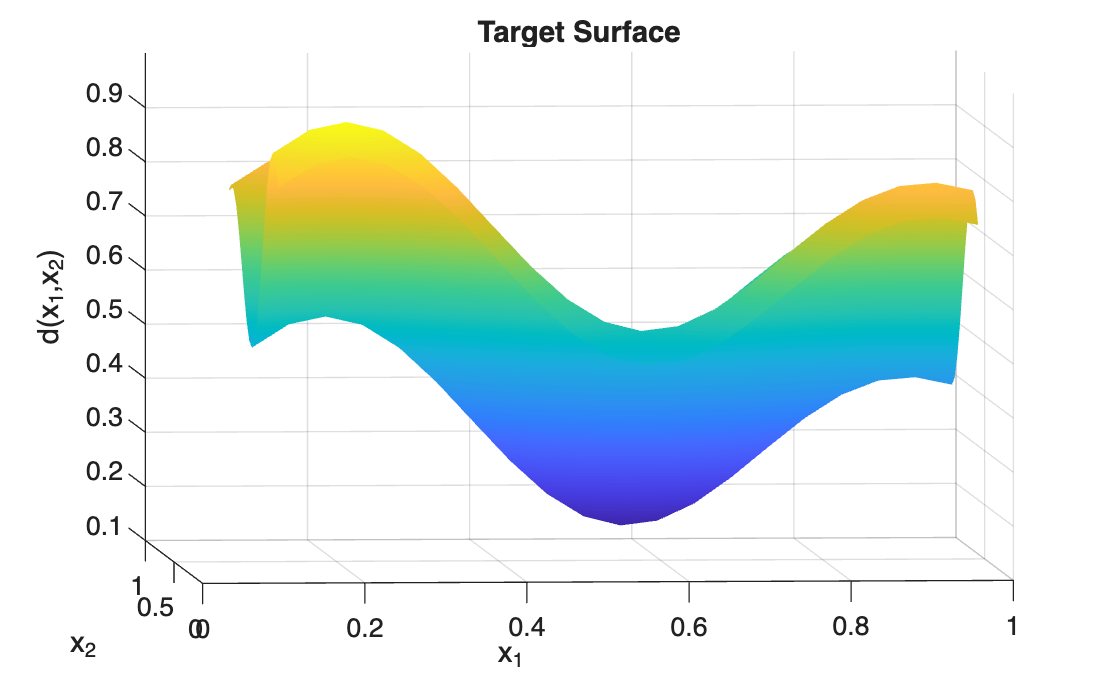

clc
clear all
close all

%% training data (2D grid)
x1 = 0.1:1/22:1;
x2 = 0.1:1/22:1;
N1 = length(x1);
N2 = length(x2);

% original 1D target function
d1_x1 = (1 + 0.6*sin(2*pi*x1/0.7) + 0.3*sin(2*pi*x1))/2;
d1_x2 = (1 + 0.6*sin(2*pi*x2/0.7) + 0.3*sin(2*pi*x2))/2;

% define surface target d(x1,x2) using same d:
% here: average of 1D targets for x1 and x2
d = zeros(N1,N2);
for i = 1:N1
    for j = 1:N2
        d(i,j) = 0.5*( ...
            (1 + 0.6*sin(2*pi*x1(i)/0.7) + 0.3*sin(2*pi*x1(i)))/2 + ...
            (1 + 0.6*sin(2*pi*x2(j)/0.7) + 0.3*sin(2*pi*x2(j)))/2 );
    end
end

figure;
surf(x1,x2,d')
title('Target Surface'); xlabel('x_1'); ylabel('x_2'); zlabel('d(x_1,x_2)'); grid on
shading interp

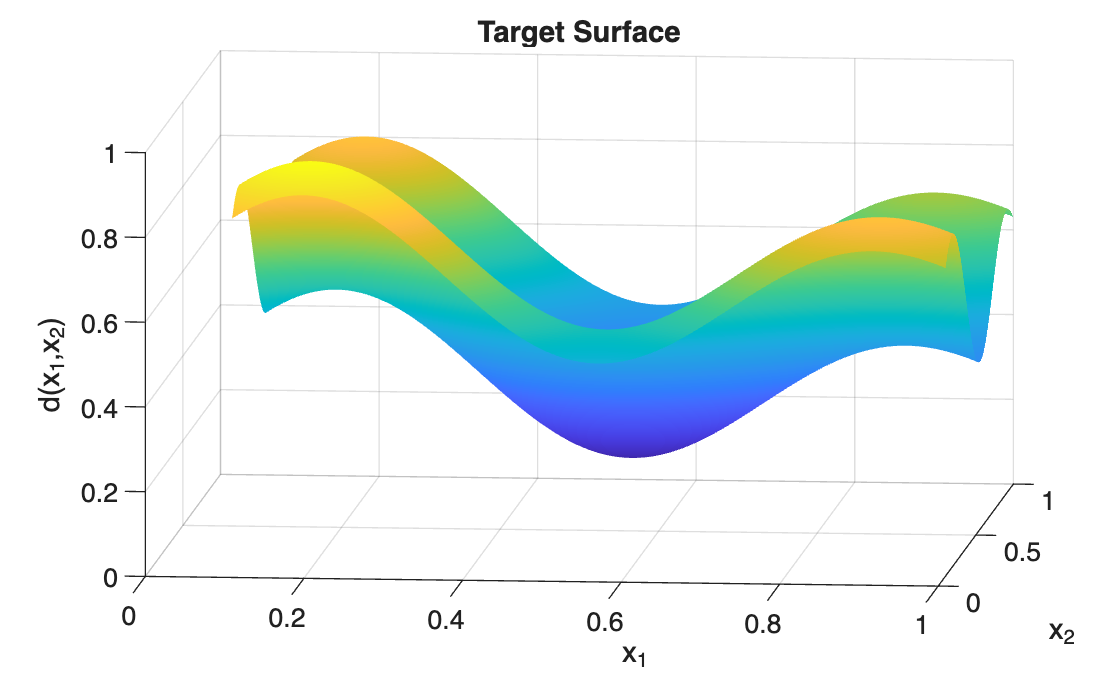


%% Parameters (6 hidden neurons, 2 inputs, 1 output)
% Hidden layer weights: each neuron now has wk1 (from x1) and wk2 (from x2)
w11_1 = rand(1); w12_1 = rand(1);  % neuron1: from x1, x2
w21_1 = rand(1); w22_1 = rand(1);  % neuron2
w31_1 = rand(1); w32_1 = rand(1);  % neuron3
w41_1 = rand(1); w42_1 = rand(1);  % neuron4
w51_1 = rand(1); w52_1 = rand(1);  % neuron5
w61_1 = rand(1); w62_1 = rand(1);  % neuron6

% Hidden layer biases
b1_1 = rand(1);
b2_1 = rand(1);
b3_1 = rand(1);
b4_1 = rand(1);
b5_1 = rand(1);
b6_1 = rand(1);

% Output layer weights (from 6 hidden neurons to output, layer 2)
w11_2 = rand(1);
w12_2 = rand(1);
w13_2 = rand(1);
w14_2 = rand(1);
w15_2 = rand(1);
w16_2 = rand(1);

% Output layer bias
b1_2 = rand(1);

eta = 0.1; % learning rate
epochs = 50000; % you may tune this

%% Training
for ep = 1:epochs
    for i = 1:N1
        for j = 1:N2

            xi1 = x1(i);
            xi2 = x2(j);
            dij = d(i,j);

            % ---- Feedforward ----
            % Hidden layer net inputs (now 2 inputs per neuron)
            v1_1 = xi1*w11_1 + xi2*w12_1 + b1_1;
            v2_1 = xi1*w21_1 + xi2*w22_1 + b2_1;
            v3_1 = xi1*w31_1 + xi2*w32_1 + b3_1;
            v4_1 = xi1*w41_1 + xi2*w42_1 + b4_1;
            v5_1 = xi1*w51_1 + xi2*w52_1 + b5_1;
            v6_1 = xi1*w61_1 + xi2*w62_1 + b6_1;

            % Hidden layer activations (sigmoid)
            y1_1 = 1/(1 + exp(-v1_1));
            y2_1 = 1/(1 + exp(-v2_1));
            y3_1 = 1/(1 + exp(-v3_1));
            y4_1 = 1/(1 + exp(-v4_1));
            y5_1 = 1/(1 + exp(-v5_1));
            y6_1 = 1/(1 + exp(-v6_1));

            % Output layer (linear)
            v1_2 = y1_1*w11_2 + y2_1*w12_2 + y3_1*w13_2 + ...
                   y4_1*w14_2 + y5_1*w15_2 + y6_1*w16_2 + b1_2;
            y1_2 = v1_2;

            % Error
            e = dij - y1_2;

            % ---- Backpropagation ----
            % Output layer delta (linear)
            delta1_2 = e;

            % Hidden layer deltas
            delta1_1 = y1_1*(1 - y1_1) * delta1_2 * w11_2;
            delta2_1 = y2_1*(1 - y2_1) * delta1_2 * w12_2;
            delta3_1 = y3_1*(1 - y3_1) * delta1_2 * w13_2;
            delta4_1 = y4_1*(1 - y4_1) * delta1_2 * w14_2;
            delta5_1 = y5_1*(1 - y5_1) * delta1_2 * w15_2;
            delta6_1 = y6_1*(1 - y6_1) * delta1_2 * w16_2;

            % ---- Update Weights ----
            % Output layer
            w11_2 = w11_2 + eta*delta1_2*y1_1;
            w12_2 = w12_2 + eta*delta1_2*y2_1;
            w13_2 = w13_2 + eta*delta1_2*y3_1;
            w14_2 = w14_2 + eta*delta1_2*y4_1;
            w15_2 = w15_2 + eta*delta1_2*y5_1;
            w16_2 = w16_2 + eta*delta1_2*y6_1;
            b1_2  = b1_2  + eta*delta1_2;

            % Hidden layer (each neuron has two input weights)
            w11_1 = w11_1 + eta*delta1_1*xi1;
            w12_1 = w12_1 + eta*delta1_1*xi2;

            w21_1 = w21_1 + eta*delta2_1*xi1;
            w22_1 = w22_1 + eta*delta2_1*xi2;

            w31_1 = w31_1 + eta*delta3_1*xi1;
            w32_1 = w32_1 + eta*delta3_1*xi2;

            w41_1 = w41_1 + eta*delta4_1*xi1;
            w42_1 = w42_1 + eta*delta4_1*xi2;

            w51_1 = w51_1 + eta*delta5_1*xi1;
            w52_1 = w52_1 + eta*delta5_1*xi2;

            w61_1 = w61_1 + eta*delta6_1*xi1;
            w62_1 = w62_1 + eta*delta6_1*xi2;

            % biases
            b1_1 = b1_1 + eta*delta1_1;
            b2_1 = b2_1 + eta*delta2_1;
            b3_1 = b3_1 + eta*delta3_1;
            b4_1 = b4_1 + eta*delta4_1;
            b5_1 = b5_1 + eta*delta5_1;
            b6_1 = b6_1 + eta*delta6_1;
        end
    end
end

%% Testing on a finer 2D grid
x1_test = 0.1:1/220:1;
x2_test = 0.1:1/220:1;
N1t = length(x1_test);
N2t = length(x2_test);

Y_pred = zeros(N1t,N2t);
Y_true = zeros(N1t,N2t);

for i = 1:N1t
    for j = 1:N2t
        xi1 = x1_test(i);
        xi2 = x2_test(j);

        % true surface
        Y_true(i,j) = 0.5*( ...
            (1 + 0.6*sin(2*pi*xi1/0.7) + 0.3*sin(2*pi*xi1))/2 + ...
            (1 + 0.6*sin(2*pi*xi2/0.7) + 0.3*sin(2*pi*xi2))/2 );

        % network prediction
        v1_1 = xi1*w11_1 + xi2*w12_1 + b1_1;
        v2_1 = xi1*w21_1 + xi2*w22_1 + b2_1;
        v3_1 = xi1*w31_1 + xi2*w32_1 + b3_1;
        v4_1 = xi1*w41_1 + xi2*w42_1 + b4_1;
        v5_1 = xi1*w51_1 + xi2*w52_1 + b5_1;
        v6_1 = xi1*w61_1 + xi2*w62_1 + b6_1;

        y1_1 = 1/(1 + exp(-v1_1));
        y2_1 = 1/(1 + exp(-v2_1));
        y3_1 = 1/(1 + exp(-v3_1));
        y4_1 = 1/(1 + exp(-v4_1));
        y5_1 = 1/(1 + exp(-v5_1));
        y6_1 = 1/(1 + exp(-v6_1));

        Y_pred(i,j) = y1_1*w11_2 + y2_1*w12_2 + y3_1*w13_2 + ...
                      y4_1*w14_2 + y5_1*w15_2 + y6_1*w16_2 + b1_2;
    end
end

%% Plotting
figure;
surf(x1_test,x2_test,Y_true')
title('Target Surface'); xlabel('x_1'); ylabel('x_2'); zlabel('d(x_1,x_2)'); grid on
shading interp

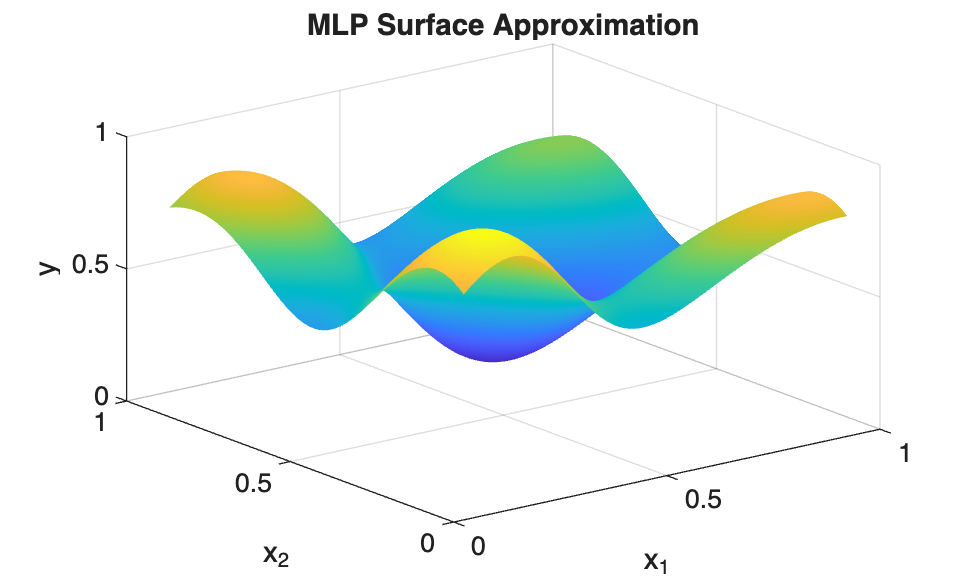


figure;
surf(x1_test,x2_test,Y_pred')
title('MLP Surface Approximation'); xlabel('x_1'); ylabel('x_2'); zlabel('y'); grid on
shading interp